function model = myLDA_train(X, y)
% X: NxD matrix (N samples, D features)
% y: Nx1 labels (assume 0 and 1)

% Separate classes
X1 = X(y == 0, :);
X2 = X(y == 1, :);

% Number of samples
N1 = size(X1, 1);
N2 = size(X2, 1);

% Means
mu1 = mean(X1, 1)';   % D x 1
mu2 = mean(X2, 1)';   % D x 1

% Within-class scatter matrix
S1 = zeros(size(X,2));
for i = 1:N1
    diff = (X1(i,:)' - mu1);
    S1 = S1 + diff * diff';
end

S2 = zeros(size(X,2));
for i = 1:N2
    diff = (X2(i,:)' - mu2);
    S2 = S2 + diff * diff';
end

Sw = S1 + S2;

% Compute weight vector
w = (Sw) \ (mu2 - mu1);

% Bias term (important)
b = -0.5 * w' * (mu1 + mu2);

% Store model
model.w = w;
model.b = b;
end

function y_pred = myLDA_predict(model, X)

w = model.w;
b = model.b;

scores = X * w + b;

% Decision
y_pred = scores >= 0;

end

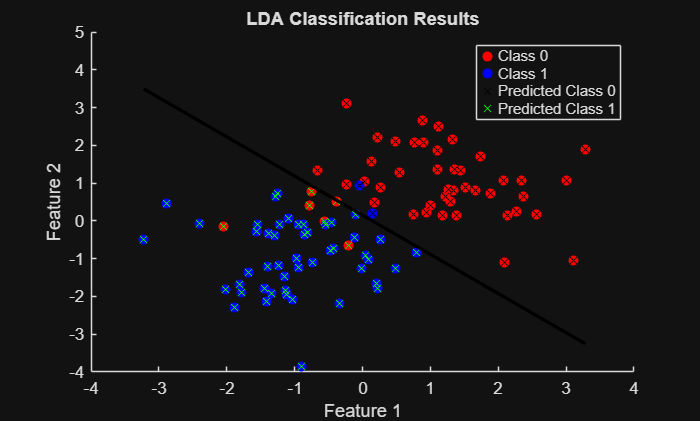

% Generate dummy data
X = [randn(50,2) + 1; randn(50,2) - 1];
y = [zeros(50,1); ones(50,1)];


% Train
model = myLDA_train(X, y);

% Predict
y_pred = myLDA_predict(model, X);
t = -4:0.01:3;
% Visualize predictions
figure;
scatter(X(y == 0, 1), X(y == 0, 2), 'r', 'filled');
hold on;
scatter(X(y == 1, 1), X(y == 1, 2), 'b', 'filled');
scatter(X(y_pred == 0, 1), X(y_pred == 0, 2), 'x', 'MarkerEdgeColor', 'k');
scatter(X(y_pred == 1, 1), X(y_pred == 1, 2), 'x', 'MarkerEdgeColor', 'g');
% Extract parameters
w = model.w;
b = model.b;

% Create line
x1_vals = linspace(min(X(:,1)), max(X(:,1)), 100);

x2_vals = -(w(1)*x1_vals + b) / w(2);

% Plot decision boundary
plot(x1_vals, x2_vals, 'k-', 'LineWidth', 2);

legend('Class 0', 'Class 1', 'LDA Boundary');
xlabel('Feature 1');
ylabel('Feature 2');
title('LDA Decision Boundary');
legend('Class 0', 'Class 1', 'Predicted Class 0', 'Predicted Class 1');
title('LDA Classification Results');
hold off;


% Accuracy
accuracy = sum(y_pred == y) / length(y);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.92
